# Music, Brain, and Emotions: An Engaging Self-Experiment

# Live-Coding 🎸🖖

2024-12-05, seung-goo.kim@ae.mpg.de

## ✅ TODOs

- [_] Import data and sanity check

- [_] Preprocessing: high-pass sampling & downsampling 

- [_] Intersubject correlation with a sliding window

- [_] Statistical inference with sign flipping

## SETUP

clear; restoredefaultpath;
[~,stdout] = system('uname -n');
if contains(stdout, "matlab-pool") % Am I on MATLAB Online?
  MATLAB_DRIVE_PATH = '/MATLAB Drive';
else
  MATLAB_DRIVE_PATH = '~/MATLAB-Drive';
end
cd ([MATLAB_DRIVE_PATH,'/mpscog-ca25-mbe/musafx-online-analysis/'])
addpath ([MATLAB_DRIVE_PATH,'/mpscog-ca25-mbe/musafx-online-analysis/code/matlab/func'])
mmo_addpath()

[mmo_addpath] (DEFAULT) Job.IsLea =    0


## Now real data🤩: IMPORT

help mmo_import()

--- mmo_import() not found. Showing help for mmo_import instead. ---

 mmo_import parses JATOS-jsPysch data of ManyMusic-Online (MM-O)
 
  Data = mmo_import(fnameTxt)



filenames = findfiles([MATLAB_DRIVE_PATH,'/mpscog-ca25-mbe/musafx-online-analysis/data/mps-main/jatos_results_data_20241205104744/*/*/data.txt'])

filenames = 26×1 cell array
    {'/Users/seung-goo.kim/MATLAB-Drive/mpscog-ca25-mbe/musafx-online-analysis/data/mps-main/jatos_results_data_20241205104744/study_result_6765/comp-result_12239/data.txt'}
    {'/Users/seung-goo.kim/MATLAB-Drive/mpscog-ca25-mbe/musafx-online-analysis/data/mps-main/jatos_results_data_20241205104744/study_result_6780/comp-result_12254/data.txt'}
    {'/Users/seung-goo.kim/MATLAB-Drive/mpscog-ca25-mbe/musafx-online-analysis/data/mps-main/jatos_results_data_20241205104744/study_result_6781/comp-result_12255/data.txt'}
    {'/Users/seung-goo.kim/MATLAB-Drive/mpscog-ca25-mbe/musafx-online-analysis/data/mps-main/jatos_results_data_20241205104744/study_result_6783/comp-result_12257/data.txt'}
    {'/Users/seung-goo.kim/MATLAB-Drive/mpscog-ca25-mbe/musafx-online-analysis/data/mps-main/jatos_results_data_20241205104744/study_result_6786/comp-result_12260/data.txt'}
    {'/Users/seung-goo.kim/MATLAB-Drive/mpscog-ca25-mbe/musafx-online-analysis/data/mps-main/jatos_res

Dataset = [];
for i = 1:numel(filenames)
  try
    Dataset = [Dataset, mmo_import(filenames{i})];
  end
end

[mmo_import|2024-12-10T10:34:33] ResponseID = "12239"
[mmo_import|2024-12-10T10:34:33] TIMELINE validity check: PASS
[mmo_import|2024-12-10T10:34:34] ResponseID = "12254"
[mmo_import|2024-12-10T10:34:34] TIMELINE validity check: PASS
[mmo_import|2024-12-10T10:34:34] ResponseID = "12255"
[mmo_import|2024-12-10T10:34:34] TIMELINE validity check: PASS
[mmo_import|2024-12-10T10:34:34] ResponseID = "12257"
[mmo_import|2024-12-10T10:34:34] TIMELINE validity check: PASS
[mmo_import|2024-12-10T10:34:34] ResponseID = "12260"
[mmo_import|2024-12-10T10:34:34] TIMELINE validity check: PASS
[mmo_import|2024-12-10T10:34:34] ResponseID = "12261"
[mmo_import|2024-12-10T10:34:34] TIMELINE validity check: PASS
[mmo_import|2024-12-10T10:34:34] ResponseID = "12263"
[mmo_import|2024-12-10T10:34:34] TIMELINE validity check: PASS
[mmo_import|2024-12-10T10:34:34] ResponseID = "12267"
[mmo_import|2024-12-10T10:34:34] TIMELINE validity check: PASS
[mmo_import|2024-12-10T10:34:34] ResponseID = "12272"
[mmo_impor

whos Dataset

  Name         Size                Bytes  Class     Attributes

  Dataset      1x25            107552748  struct              



## Q1: Effect of axis orientations

HINT: 1126700 = "Trumpet Jazz Quintet (5:45)", 1374300="Piano day-dreaming (3:19)", 1332599="Fusion Funk (4:00)"

Y = mmo_prep(Dataset, struct(TrackId=1126700, HighPassHz=0, SamplingRateHz=1));

[mmo_prep] (DEFAULT) Cfg.ToiSec =     15   -15



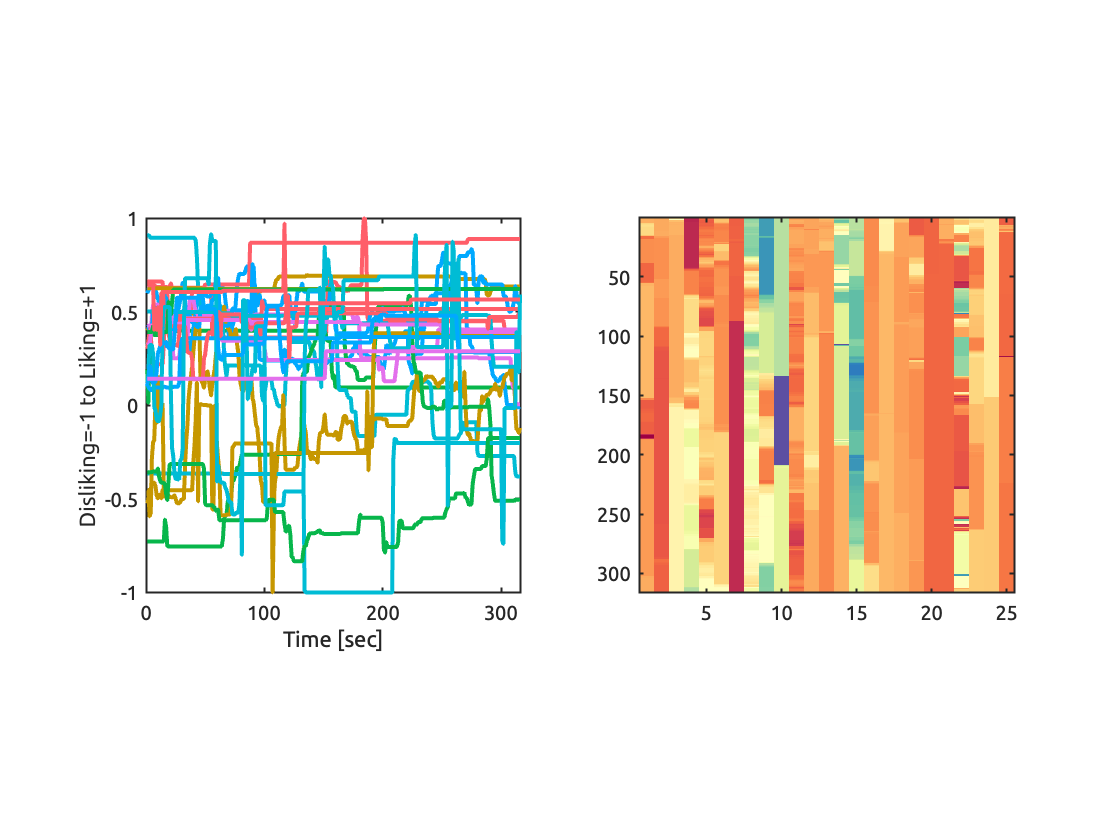

subplot(121); plot(Y.DislikingToLiking); axis square; ylabel('Disliking=-1 to Liking=+1'); xlabel('Time [sec]')
subplot(122); imagesc(Y.DislikingToLiking, [-1 1]); axis square

subplot(121); plot(Y.RelaxedToExcited); axis square; ylabel('Relaxed=-1 to Excited=+1'); xlabel('Time [sec]')
subplot(122); imagesc(Y.RelaxedToExcited, [-1 1]); axis square

function isc = compute_isc(Y)
isc = [];
sumY = sum(Y,2);
for i = size(Y,2):-1:1
  isc(i) = corr(sumY-Y(:,i), Y(:,i));
end

end
iscArousal = compute_isc(Y.RelaxedToExcited);
iscLiking = compute_isc(Y.DislikingToLiking);
clf; subplot(211); histogram(iscArousal); axis square; xlabel('ISC')
title(sprintf('Arousal: M=%.2f, SD=%.2f', mean(iscArousal), std(iscArousal))); xlim([-1 1])

subplot(212); histogram(iscLiking); axis square; xlabel('ISC')
title(sprintf('Liking: M=%.2f, SD=%.2f', mean(iscLiking), std(iscLiking))); xlim([-1 1])

Okay... but how do I test the effect of axes on ISC?

figure; 

ans = 1×7 string array
    "DLRE"    "ERDL"    "ERLD"    "LDER"    "LDRE"    "REDL"    "RELD"


iscMtx = corr(Y.RelaxedToExcited);
imagesc(iscMtx); axis square
Patterns = string();
for i = 1:numel(Dataset)
  Patterns(i) = string([ ...
    Dataset(i).Spotify{1}.Properties.UserData.OrigAxisLabels.xLabelNegative(1), ...
    Dataset(i).Spotify{1}.Properties.UserData.OrigAxisLabels.xLabelPositive(1), ...
    Dataset(i).Spotify{1}.Properties.UserData.OrigAxisLabels.yLabelNegative(1), ...
    Dataset(i).Spotify{1}.Properties.UserData.OrigAxisLabels.yLabelPositive(1)]);
end
unique(Patterns)
withinIsc = [];
betweenIsc = [];
for iPat = 1:numel(Patterns)
  idxSub = Patterns == Patterns(iPat);
  subMat = iscMtx(idxSub, idxSub);
  withinIsc = [withinIsc; subMat(~~triu(ones(size(subMat)),1))];
  % withinIsc = [withinIsc; reshape(subMat(~~eye(size(subMat))), [], 1)];


  idxOthers = Patterns ~= Patterns(iPat);
  subMat = iscMtx(idxSub, idxOthers);
  betweenIsc = [betweenIsc; subMat(:)];
end

clf; 
subplot(121); imagesc(iscMtx,[-1 1]); axis square
subplot(122); h = plotridgelines({withinIsc, betweenIsc}); axis square
legend(h, ["within", "between"])
xlabel('ISC-arousal')
iscMtx = corr(Y.DislikingToLiking);
withinIsc = [];
betweenIsc = [];
for iPat = 1:numel(Patterns)
  idxSub = Patterns == Patterns(iPat);
  subMat = iscMtx(idxSub, idxSub);
  withinIsc = [withinIsc; subMat(~~triu(ones(size(subMat)),1))];


  idxOthers = Patterns ~= Patterns(iPat);
  subMat = iscMtx(idxSub, idxOthers);
  betweenIsc = [betweenIsc; subMat(:)];
end

clf;
subplot(121); imagesc(iscMtx,[-1 1]); axis square
subplot(122);
h = plotridgelines({withinIsc, betweenIsc}); axis square
legend(h, ["within", "between"])
xlabel('ISC-liking')